# Pràctica Fúmbol

## 1. Introducció

Aquest projecte consisteix a desenvolupar un programa que sigui capaç de reconèixer automàticament imatges on hi hagi una presència significativa de la samarreta del** F.C.Barcelona**.

Per dur a terme el que se'ns demana, utilitzarem imatges normalitzades, histogrames de colors, l'algoritme *chi-quadrat* explicat a teoria i dues formes diferents de dividir/recorrer imatges.

## 2. Selecció del model

Primer de tot, escollim una de les imatges proporcionades del barça com a model, la normalitzem i escollim una subimatge que serà la que ens servirà com a *patró*. Aquesta subimatge no serà més que un tros de la samarreta del F.C.Barcleona on es puguin distingir bé els colors i, per tant, poguem extreure un bon histograma.

La funció que utilitzem per visualitzar l'histograma i decidir si utilitzar la imatge escollida com a model és *histRB*, una funció nostra que conté la funció *histogram*, la qual pertany a una llibreria de gràfics de Matlab. 

La funció que utilitzem per extreure les dades de l'histograma és *histcountRB*, funció nostra que conté la funció *histcounts*, la qual pertany a una llibreria de gràfics de Matlab. D'aquesta, però, ens guardem els resultats ja que seran els que utilitzarem a l'hora de comparar altres imatges.

El valor d'*nbins *s'ha escollit després de fer vàries proves i concloure que aquest valor és amb el que millors resultats hem obtingut.

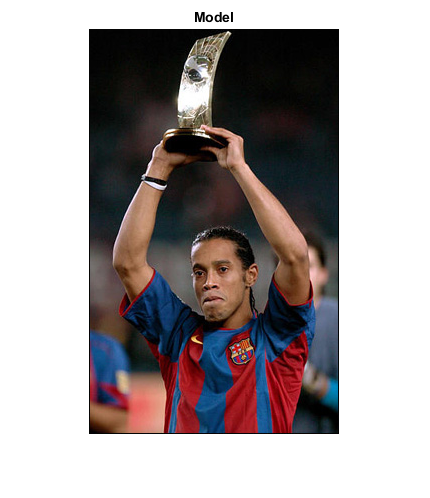

im = imread('model.jpg');
figure, imshow(im); title('Model');

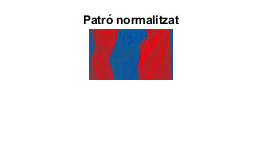


imd = im2double(im);
img = normalizeRGB(imd);
pattern = img(350:400,87:170,:);
figure, imshow(pattern); title('Patró normalitzat')

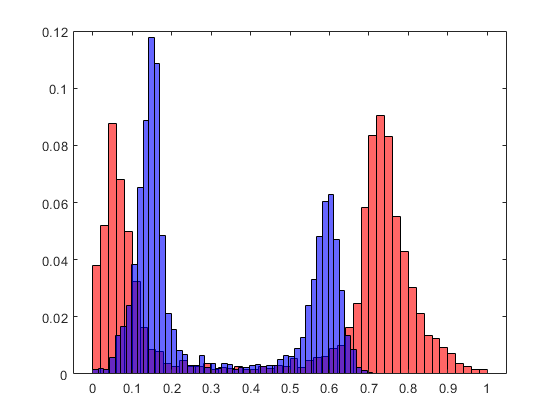


figure, histRB(pattern,50);

[model_red, model_blue] = histcountRB(pattern, 50);

## 3. Comparació d'imatges: RGB

### 3.1. Mètode de divisió #1

Agafem una imatge diferent de la del model, la normalitzem amb una funció nostra *normalizeRGB* com vam fer a una de les sessions de laboratori i la passem sencera a la funció nostra *computeQuadrants*. Aquesta funció és una funció recursiva que el que fa és cridar a la funció nostra *divideix, *la qual divideix la funció en 4 parts de mida igual (o semblan en cas de que les mides siguin senars). Després, fa l'histograma de cadascuna de les subimatges amb *histcountRB* com s'ha explicat a l'apartat anterior, computa la diferència entre l'histograma model i l'histograma que acabem de generar i fixa el mínim entre els resultats obtingut i els inicials o els computats anteriorment. Això es fa amb les funcions *chiSquare, *funció creada per nosaltres però la formula emprada és la que es descriu a les transparències de teoria i la funció *setMinimum, *la qual és nostra també i l'únic que fa és retornar el mínim entre 2 valors.

Finalment fa la crida recursiva amb cada subimatge i torna a fer el mateix. L'objectiu d'aquesta funció és retornar la menor diferència d'histogrames de la imatge que es compara amb el patró.

El mètode utilitzar per dividir la imatge és el *top-down* explicat a teoria amb la diferència que no s'arriba a nivell de pixel sinó que para quan ja ha fet 4 iteracions. Aquesta cota l'hem escollida a base de fer proves i obtenir millors resultats. 

A continuació, passarem totes les imatges de l'equip F.C.Barcelona pel nostre mètode i n'extreurem un llindar amb el qual es puguin reconèixer la majoria d'imatges d'aquest equip i es minimitzin les que pot reconèixer com a falsos positius d'altres equips. 

El llindar escollit com a diferencia màxima entre els histogrames és de 0'45. I els resultats obtinguts és que reconeix un 66'67% de les imatges del barça.

Per visualitzar millor els resulats, hem fet una gràfica de barres amb la funció *bar* de la llibreria de gràfics de Matlab. Les barres que representen la similitud entre les imatges i el patró que estan per sota del llindar seleccionat sortiran pintades de color lila i seran reconegudes com a imatges de l'equip mentre que les que no ho estiguin sortiran en color blau.

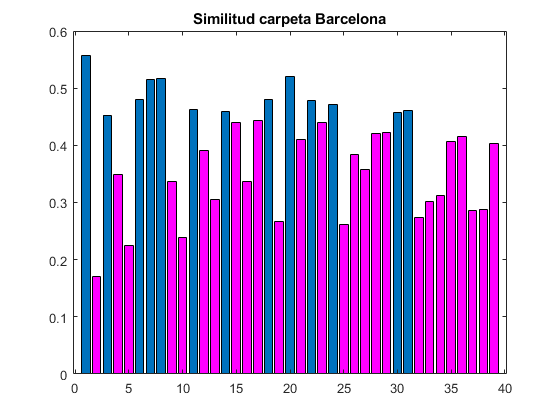

size = 39;
y = zeros(1,size);

for i = 1:size
    novaim = imread(['barcelona/',num2str(i),'.jpg']);
    novaimg = im2double(novaim);
    novanorm = normalizeRGB(novaimg);    
    [red,blue] = computeQuadrants(model_red, model_blue, novanorm, 50,0,2,2);
    y(i) = (red+blue)/2;
end

figure, 
b = bar(y,'FaceColor', "flat"); title('Similitud carpeta Barcelona');
count = 0;
for i = 1:size
    if y(i) < 0.45
        b.CData(i,:) = [1 0 1];
        count = count + 1;
    end
end

total_rec = count/size *100;
disp(strcat("Total reconegudes de Barcelona: ", num2str(total_rec), '%'))

Total reconegudes de Barcelona: 66.6667%


Finalment, passem la resta d'imatges de la resta d'equips pel nostre mètode i visualitzem els resultats. Com a l'apartat anterior, per facilitar aquesta tasca hem fet un gràfic de barres amb les mateixes condicions que abans. A destacar principal els falsos positius amb el chelsea (45%) i el liverpool (40%).

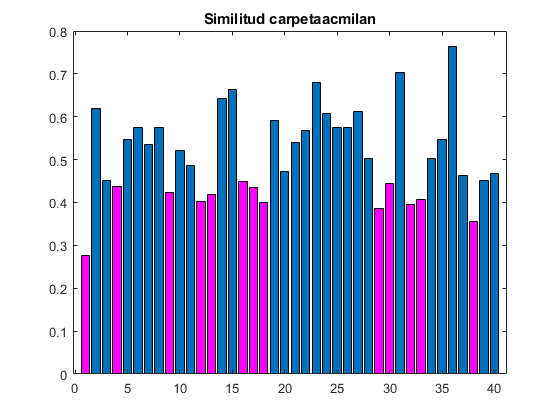

Falsos positius de acmilan:32.5%


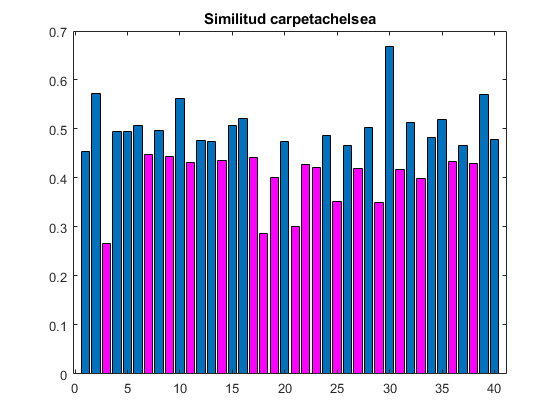

Falsos positius de chelsea:45%


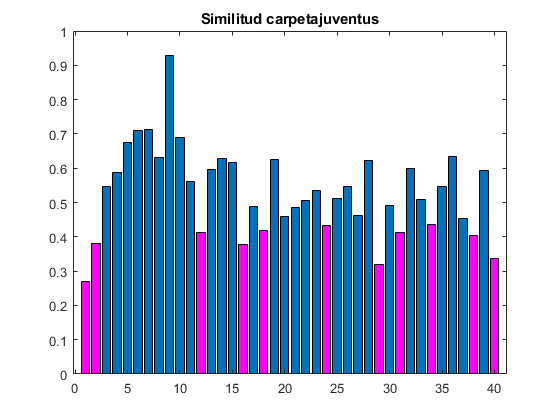

Falsos positius de juventus:27.5%


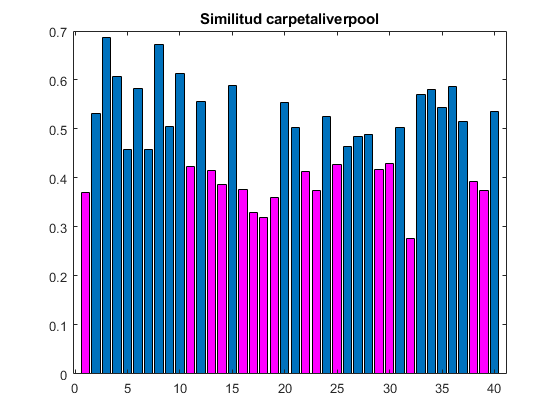

Falsos positius de liverpool:40%


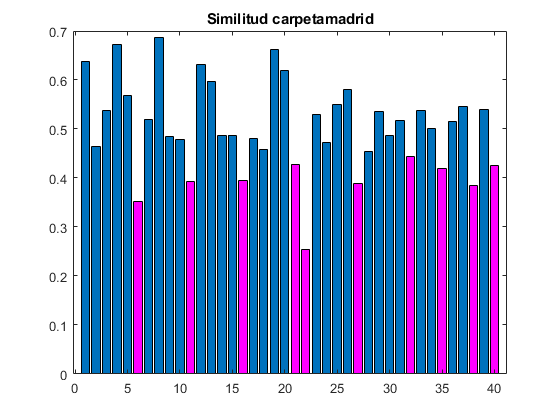

Falsos positius de madrid:25%


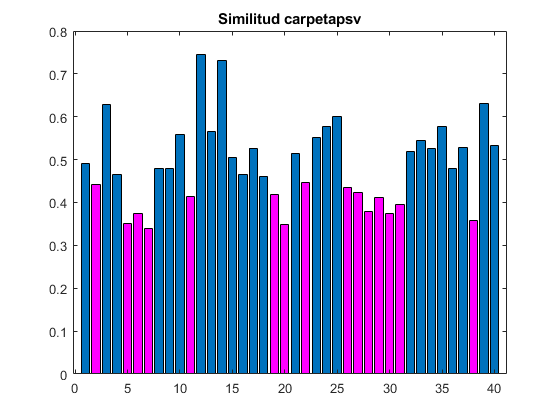

Falsos positius de psv:37.5%


size = 40;
y = zeros(1,size);

folders = ["acmilan", "chelsea", "juventus", "liverpool", "madrid", "psv"];

for team = 1:6
    for i = 1:size
        novaim = imread(strcat(folders(team), '/',num2str(i),'.jpg'));
        novaimg = im2double(novaim);
        novanorm = normalizeRGB(novaimg);    
        [red,blue] = computeQuadrants(model_red, model_blue, novanorm, 50,0, 2, 2);
        y(i) = (red+blue)/2;
    end

    figure, 
    b = bar(y,'FaceColor',"flat"); title(strcat('Similitud carpeta ', ' ', folders(team)));
    
    count = 0;
    for i = 1:size
        if y(i) < 0.45
            b.CData(i,:) = [1 0 1];
            count = count + 1;
        end
    end
    falsos_positius = count/size *100;
    disp(strcat("Falsos positius de ", folders(team), ': ', num2str(falsos_positius), '%'))
end

### 3.2. Mètode de divisió #2

Per aquest mètode de divisió el que fem és recórrer totes les subimates d'un tamany determinat de la imatge a reconèixer. La mida de la subimatge s'ha escollit a partir de fer vàries proves. Al principi vàrem provar amb subimatges de la mida del patró escollit, però el temps d'execució es torna massa gran.

El que fa el programa és primer calcular l'histograma del patró i després s'usa la funció imsweep creada per nosaltres. Aquesta funció rep la imatge a reconèixer i la normalitza entre 0 i 1. Després mira totes les subimatges d'una mida determinada de la imatge, de cada subimatge en calcula l'histograma i a partir dels valors d'aquest, calcula la distància chi-quadrat. La funció retorna el valor de chi mínim d'entre totes les subimatges.

hist_im = histcounts(pattern, 50)./numel(pattern);
pattern_rows = 100;
pattern_cols = 70;
nbins = 50;
size = 20;
accept_threshold = 0.32;

Amb el mètode comentat anteriorment intentarem reconèixer les imatges de la carpeta de Barcelona, i escollirem un llindar d'acceptació que minimitzi els falsos positius i maximitzi els positius. Per visualitzar els resultats farem el mateix que en els altres apartats.

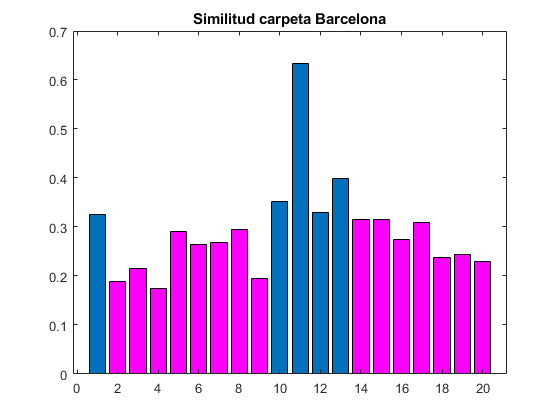

y = zeros(1,size);

for i = 1:size
    novaim = imread(['barcelona/',num2str(i),'.jpg']);
    y(i) = imsweep(hist_im, novaim, nbins, pattern_rows, pattern_cols);
    
end

figure, 
b = bar(y,'FaceColor',"flat"); title('Similitud carpeta Barcelona');

count = 0;
for i = 1:size
    if y(i) < accept_threshold
        b.CData(i,:) = [1 0 1];
        count = count + 1;
    end
end

total_rec = count/size *100;
disp(strcat("Total reconegudes de Barcelona: ", num2str(total_rec), '%'))

Total reconegudes de Barcelona: 75%


Després farem el mateix amb la resta d'equips. Podem observar que els equips de Liverpool i Chelsea donen un gran nombre de falsos positius, probablement pel fet que les samarretes són vermelles i blaves respectivament, i per tant el nostre sistema de reconeixement les detecta com més similars a les del Barça. Degut al alt cost computacional d'aquest metode el temps d'execució és molt elevat, per tant no hem executat per a totes les imatges, i nomès per a un subconjunt, que ens servirà per extreure conclusions.

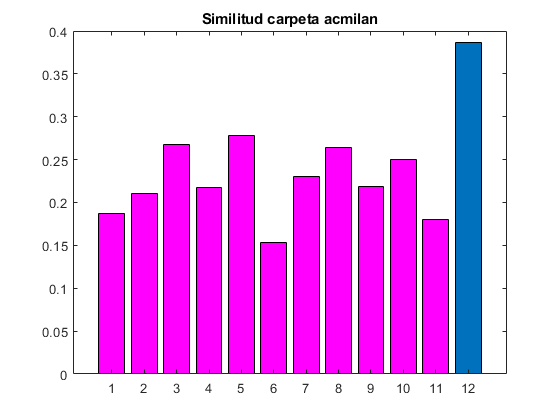

Falsos positius de acmilan:91.6667%


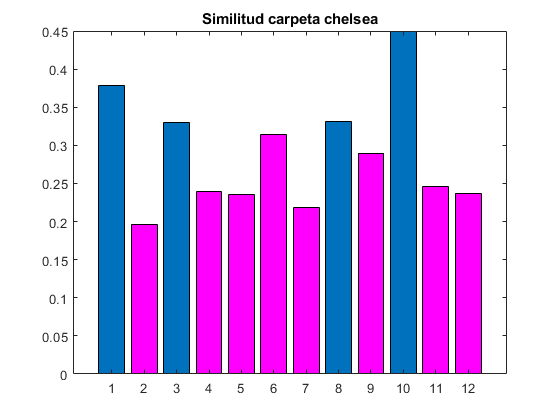

Falsos positius de chelsea:66.6667%


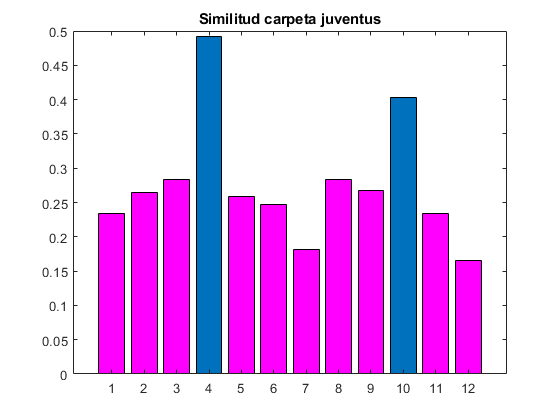

Falsos positius de juventus:83.3333%


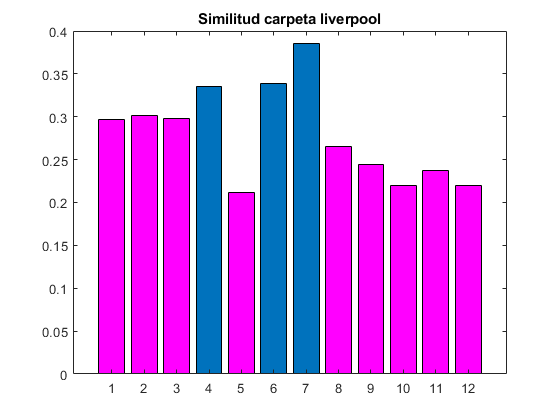

Falsos positius de liverpool:75%


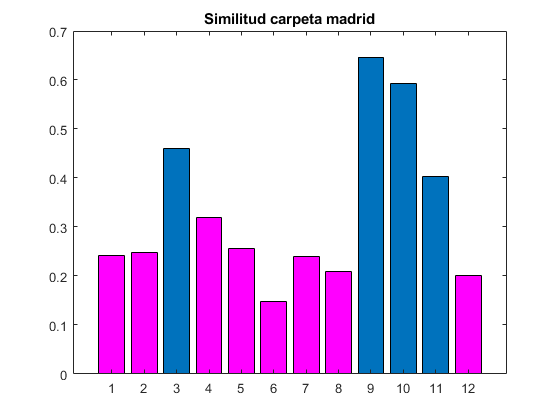

Falsos positius de madrid:66.6667%


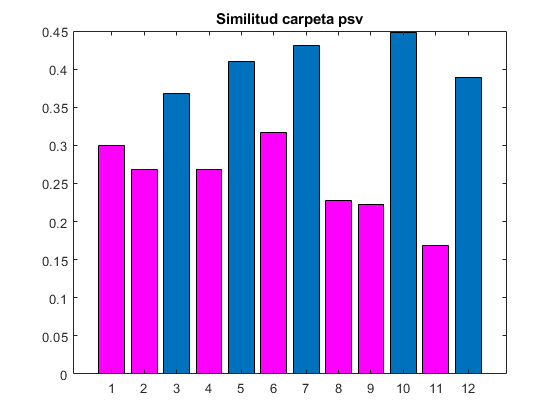

Falsos positius de psv:58.3333%


size = 12;
y = zeros(1,size);

folders = ["acmilan", "chelsea", "juventus", "liverpool", "madrid", "psv"];

for team = 1:6
     for i = 1:size
         im = imread(strcat(folders(team), '/',num2str(i),'.jpg'));
         y(i) = imsweep(hist_im, im, 50, pattern_rows, pattern_cols);
    end

    figure, 
    b = bar(y,'FaceColor',"flat"); title(strcat("Similitud carpeta ", folders(team)));
    
    count = 0;
    for i = 1:size
        if y(i) < accept_threshold
            b.CData(i,:) = [1 0 1];
            count = count + 1;
        end
    end
    falsos_positius = count/size *100;
    disp(strcat("Falsos positius de", " ",folders(team), ': ', num2str(falsos_positius), '%'))
end

## 4. Comparació d'imatges: HSV 

### 4.1. Mètode de divisió #1

Ara, farem exactament el mateix pero en comptes de tenir la imatge en RGB, la tindrem en HSV. Així que, normalitzem la imatge amb *v=0 *a la funció nostra *normalizeHSV, *on normalitzem com a una sessió de laboratori. Agafem la mateixa imatge model i el mateix patró i fem histograma amb la funció nostra *histcountHS *que fa el mateix que la funció *histcountRB* però cambiant el component *r *per l'*h* i el *b *pel *s. *

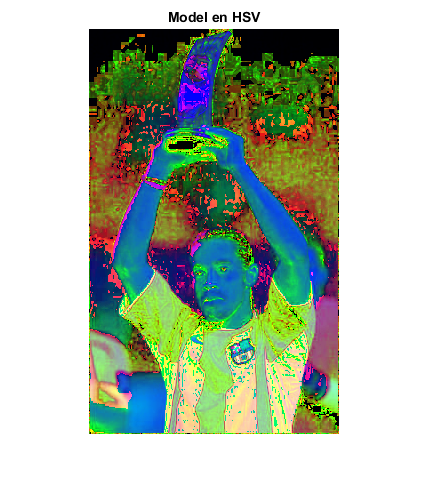

im = imread('model.jpg');
im = rgb2hsv(im);
figure, imshow(im); title('Model en HSV');

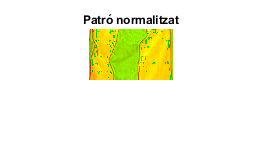

im = normalizeHSV(im);
pattern = im(350:400,87:170,:);
[mh, ms] = histcountHS(pattern, 50);
figure, imshow(pattern); title('Patró normalitzat');

Seguidament passem totes les imatges del F.C.Barcelona i escollim un límit amb les mateixes condicions que a RGB. El mètode de divisió seguit és el descrit anteriorment a l'apartat *4.1 *i les funcions són les mateixes però adaptant-les a HSV. 

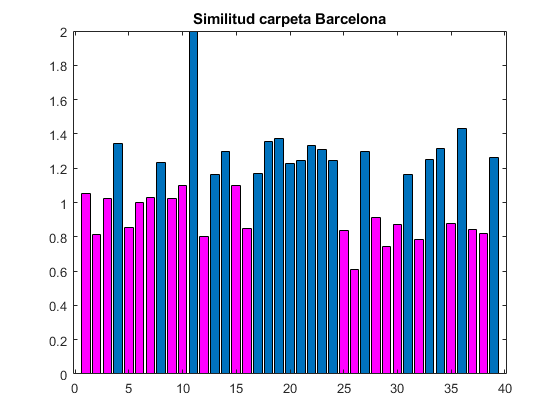

size = 39;
y = zeros(1,size);

for i = 1:size
    novaim = imread(['barcelona/',num2str(i),'.jpg']);
    novaimg = rgb2hsv(novaim);
    novanorm = normalizeHSV(novaimg);    
    [h,s] = computeQuadrantsHSV(mh,ms,novanorm,50,0,2,2);
    y(i) = (h+s)/2;
end

figure, 
b = bar(y,'FaceColor',"flat"); title('Similitud carpeta Barcelona');

count = 0;
for i = 1:size
    if y(i) < 1.1
        b.CData(i,:) = [1 0 1];
        count = count + 1;
    end
end

Total_reconegudes = [num2str(count/size *100),'%']

Total_reconegudes = '51.2821%'

Tornem a passar tota la resta d'imatges com hem fet amb RGB i extreiem els resultats. Com podem veure, tornem a tenir clars problemes amb els equips *acmilan *(50%) i *liverpool *(57%) de falsos postius*.*

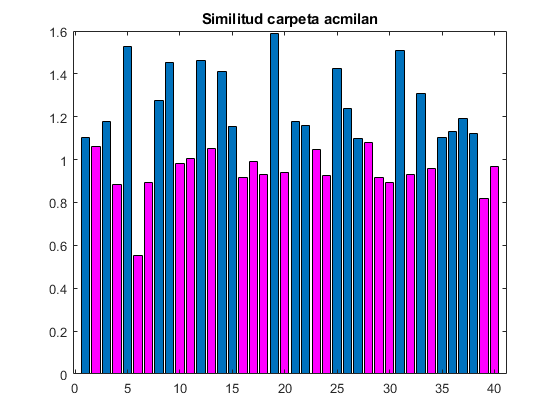

Falsos positius de acmilan:50%


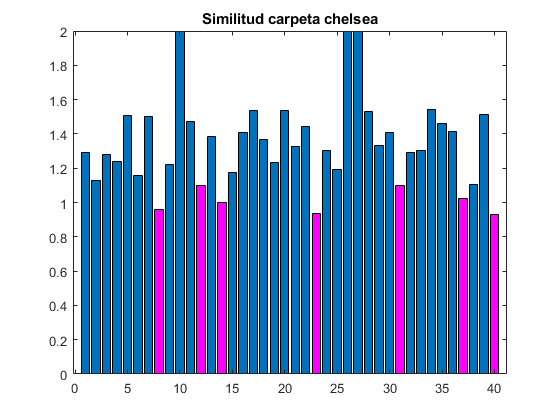

Falsos positius de chelsea:17.5%


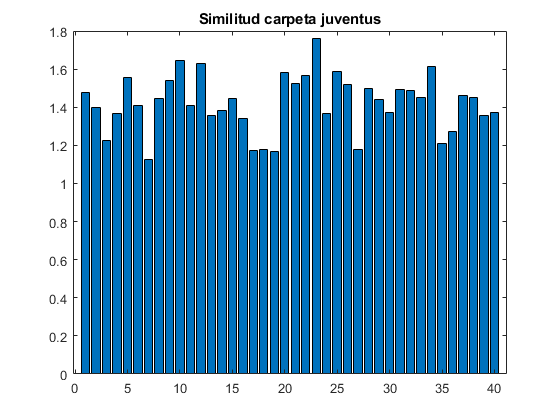

Falsos positius de juventus:0%


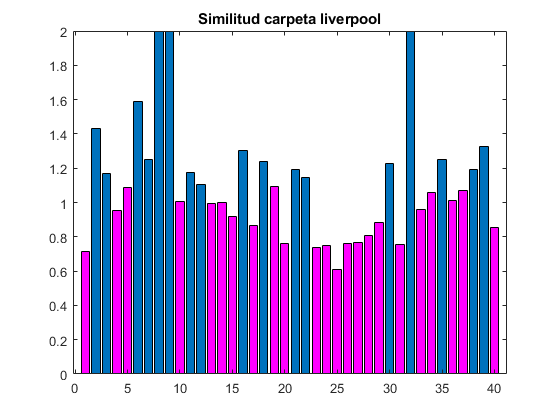

Falsos positius de liverpool:57.5%


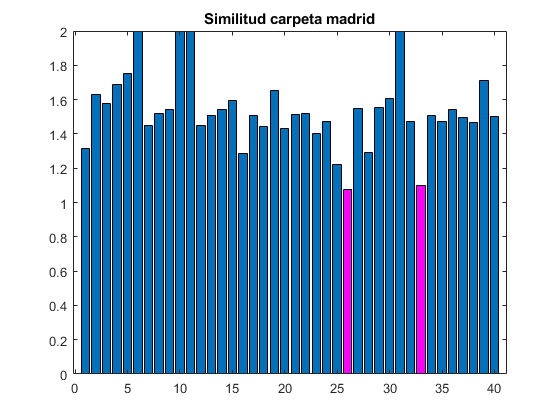

Falsos positius de madrid:5%


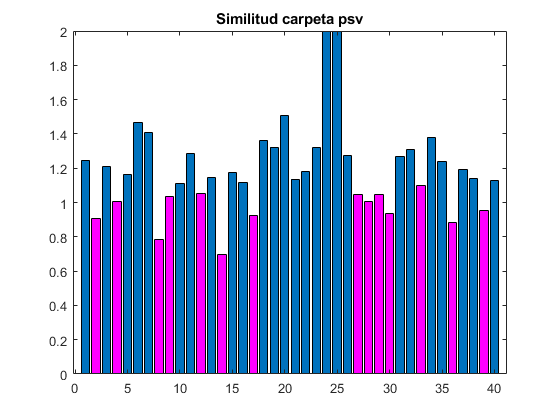

Falsos positius de psv:35%


size = 40;
y = zeros(1,size);

folders = ["acmilan", "chelsea", "juventus", "liverpool", "madrid", "psv"];

for team = 1:6
    for i = 1:size
        novaim = imread(strcat(folders(team), '/',num2str(i),'.jpg'));
        novaimg = rgb2hsv(novaim);
        novanorm = normalizeHSV(novaimg);    
        [h,s] = computeQuadrantsHSV(mh,ms,novanorm,50,0,2,2);
        y(i) = (h+s)/2;
    end

    figure, 
    b = bar(y,'FaceColor',"flat"); title(strcat("Similitud carpeta ", folders(team)));
    
    count = 0;
    for i = 1:size
        if y(i) < 1.1
            b.CData(i,:) = [1 0 1];
            count = count + 1;
        end
    end
    falsos_positius = count/size *100;
    disp(strcat("Falsos positius de", " ",folders(team), ': ', num2str(falsos_positius), '%'))
end

### 4.2. Mètode de divisió #2

Utilitzarem el mateix mètode que hem utilitzat per RGB amb la imatge passada a HSV. Al passar la imatge RGB a HSV amb la funció de matlab rgb2hsv la normalitzarem amb la nostra funció normalizeHSV. Després de crear el patró agafarem el valor de l'histograma de les components H i S per tal de comparar-los amb les altres imatges.

im = imread('model.jpg');
im = rgb2hsv(im);
im = normalizeHSV(im);
pattern = im(350:400,87:170,:);
[mh, ms] = histcountHS(pattern, 50);
nbins = 50;
accept_threshold = 0.7;

Igual que amb les imatges RGB, compararem les subimatges, però aquesta vegada usarem la funció *imsweepHSV, *que és la versió adaptada de la funció *imsweep *utilitzada anteriorment. Aquesta compara les components H i S del patró amb les components H i S de totes les subimatges de la imatge a reconèixer. Despes de veure els resultats amb els gràfics de barra, escollirem un llindar per minimitzar els falsos positius i reconèixer el màxim de positius.

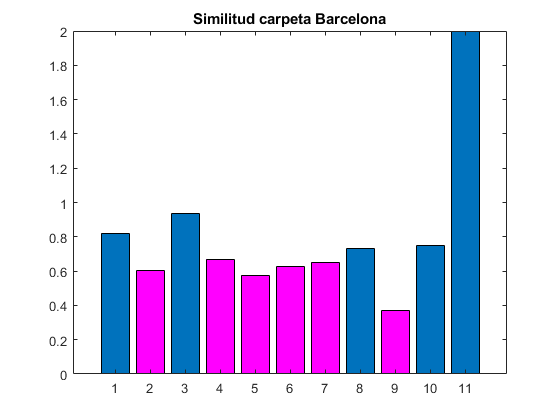

size = 11;
y = zeros(1,size);

for i = 1:size
    im = imread(['barcelona/',num2str(i),'.jpg']);
        y(i) = imsweepHSV(mh, ms, im, nbins, pattern_rows, pattern_cols);
end

figure, 
b = bar(y,'FaceColor',"flat"); title('Similitud carpeta Barcelona');

count = 0;
for i = 1:size
    if y(i) < accept_threshold
        b.CData(i,:) = [1 0 1];
        count = count + 1;
    end
end

Total_reconegudes = [num2str(count/size *100),'%']

Total_reconegudes = '54.5455%'

Ara farem el mateix amb la resta d'equips per tal de poder avaluar els resultats.

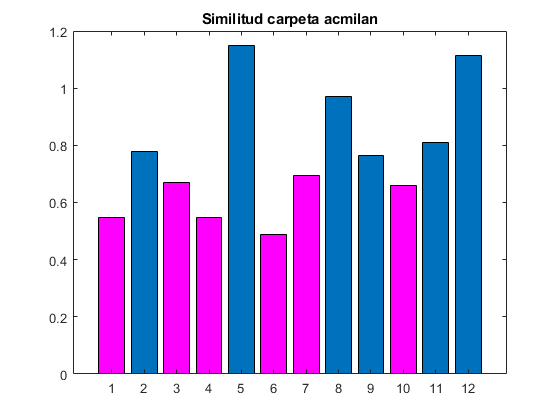

Falsos positius de acmilan:50%


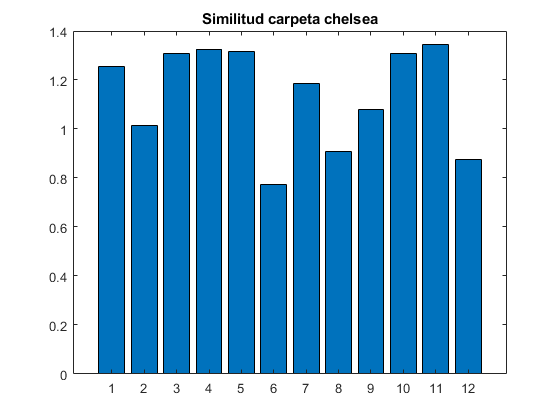

Falsos positius de chelsea:0%


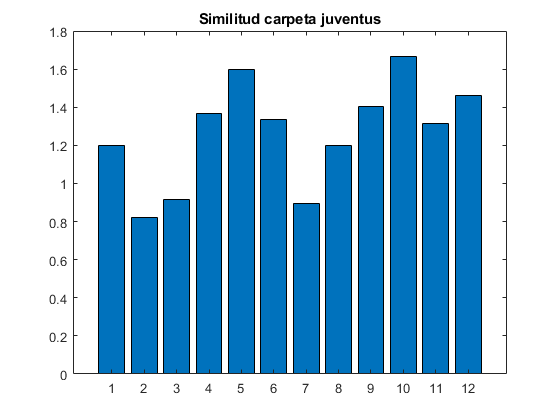

Falsos positius de juventus:0%


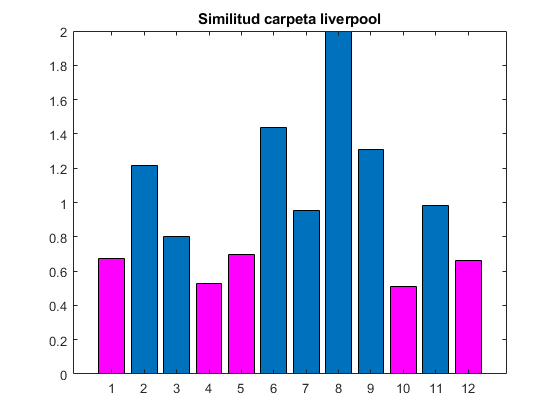

Falsos positius de liverpool:41.6667%


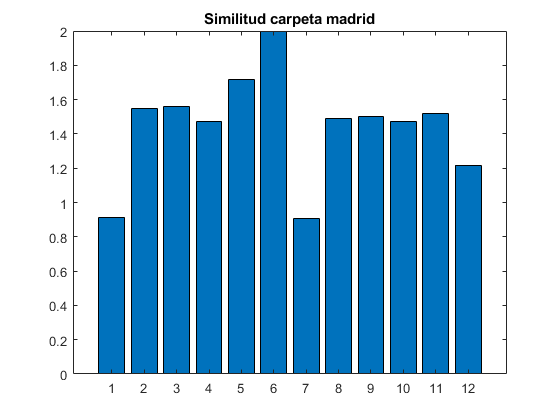

Falsos positius de madrid:0%


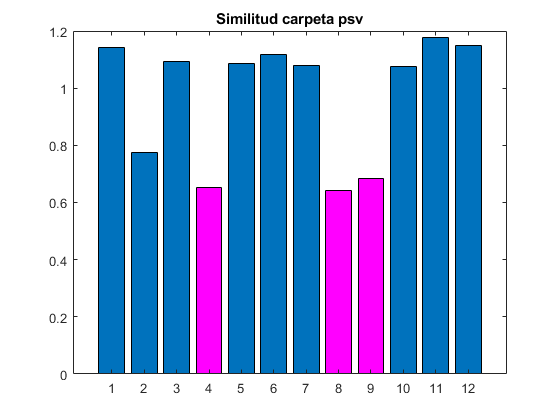

Falsos positius de psv:25%


size = 12;
y = zeros(1,size);

folders = ["acmilan", "chelsea", "juventus", "liverpool", "madrid", "psv"];

for team = 1:6
     for i = 1:size
         im = imread(strcat(folders(team), '/',num2str(i),'.jpg'));
        y(i) = imsweepHSV(mh, ms, im, nbins, pattern_rows, pattern_cols);
    end

    figure, 
    b = bar(y,'FaceColor',"flat"); title(strcat("Similitud carpeta ", folders(team)));
    
    count = 0;
    for i = 1:size
        if y(i) < accept_threshold
            b.CData(i,:) = [1 0 1];
            count = count + 1;
        end
    end
    falsos_positius = count/size *100;
    disp(strcat("Falsos positius de", " ",folders(team), ': ', num2str(falsos_positius), '%'))
end

## Conclusions

Hem utilitzat dos mètodes de dividir la imatge, per tant els podem comparar. El mètode de comparar totes les subimatges d'una determinada mida és molt més costós en termes de temps, ja que es realitzen moltes comparacions (~100.000 per imatge) i no aconsegueix uns resultats significativament millors. Tot i això és interessant poder comparar els dos mètodes.

Com podem observar, amb el primer mètode de divisió s'obtenen resultats notablement millors en RGB però amb el segon en són millors els d'HSV. En general, els resultats amb millor tasa de reconeguts i falsos positius és HSV amb el segon mètode de divisió. Així que, tot i que trigui bastant més, val la pena executar aquesta modalitat si el que volem és obtenir la major fiabilitat. Si el que volem és algo ràpid però que pugui fallar, el primer mètode amb RGB seria l'opció adient.

Els resultats més negatius han estat amb els equips del Chelsea, ja que té la samarreta blava i el Liverpool i el ACMilan, que la tenen vermella. Com que aquests són els colors de la samarreta del Barça, el nostre programa reconeix més similitud en aquests dos equips i per tant hi ha un elevat nombre de falsos positius.

Altres mètodes provats que no ens van donar bons resultats van ser el Root Mean Squared Error (RMSE) i la divergència Kullback–Leibler per comparar histogrames. Cap d'aquests dos mètodes ens van dónar resultats millors dels obtinguts amb la distància Chi-Square.

També vam provar diferents mètodes pel preprocessat de les imatges, com diferents normalitzacions per a la imatge i els seus canals, o la normalització dels histogrames amb diferents tècniques. Després de realitzar proves el mètode que donava millor resultat és l'escollit.